# Diffusion Monte Carlo

Description...

## Global Constants

hbar = 1;                % Reduced Plank's constant (in atomic units)
me = 1;                  % Electron mass (in atomic units)
D = hbar^2/(2*me);       % Diffusion constant for electron

## Pseudorandom Numbers

Diffusion Monte Carlo makes use of pseudorandom numbers. In order for these results to be reproducible, it is important to choose a particular random number generator and seed. I chose the following seed by running `randi(1e6)` in MATLAB. Every time I do something random, I set the seed so that the results are reproducible. If you are running this notebook, feel free to change the seeds in order to test the results for yourself.

# One-Dimensional Harmonic Oscillator

Our first test will be the one-dimensional harmonic oscillator potential.

dims = 1;                      % Dimensions of the problem
w = 1;                         % Angular frequency
V = @(x) (1/2)*me*w^2*x^2;     % 1D harmonic oscillator potential

## Exact Ground State

For this potential, the Shrödinger equation can be solved exactly.

psi0 = @(x) (me*w/(pi*hbar))^(1/4)*exp(-me*w*x.^2/(2*hbar));  % Ground state wave function
Eexact = (1/2)*hbar*w;                                        % Ground state energy
sdx = sqrt(hbar/(2*me*w));                                    % Standard deviation of position

## Unguided Diffusion Monte Carlo

Using the values from [paper], ...

rng(254533);
M = 100;                     % Initial number of walkers
R0 = (rand(M,1)-0.5).*sdx;   % Starting positions for walkers 
E0 = 1;                      % Initial energy estimate
dt = 0.01;                   % Time step
steps = 1000;                % Total number of steps for simulation
bSteps = 20;                 % Energy estimate E0 adjusted every bSteps steps
a = 0.01;                    % Proportionality factor

Now we'll run the simulation

[E, R] = DMCnaive(D,dims,V,R0,E0,dt,M,steps,bSteps,a);

The energy estimate from this simulation is:

E

The unit of energy in atomic units is the hartree. The true energy estimate, in hatree, is 0.5. We can also plot the solution:

plotDMC(psi0,R,20,[-1,1]*3.5)
title('Figure 1: Ground State of Electron in Harmonic Oscillator (Unguided)')
xlabel('Distance (bohr)')
ylabel('Wave Function')

### Statistical Error

rng(801362);
N = 100;
samples = zeros(N,1);
parfor i = 1:N
    samples(i) = DMCnaive(D,dims,V,R0,E0,dt,M,steps,bSteps,a);
end
mean(samples)
std(samples)

After equilibrium is reached, number of steps does not necessarily make it more accurate. Time step could, but I found I needed to adjust `a` as well

M = 100;                     % Initial number of walkers
R0 = (rand(M,1)-0.5).*sdx;   % Starting positions for walkers 
E0 = 1;                      % Initial energy estimate
dt = 0.001;                  % Time step
steps = 1000;                % Total number of steps for simulation
bSteps = 20;                 % Energy estimate E0 adjusted every bSteps steps
a = 0.001;                   % Proportionality factor
tic; [E, R] = DMCnaive(D,dims,V,R0,E0,dt,M,steps,bSteps,a); toc;
E

## Guided Diffusion Monte Carlo

### Sampling a distribution

We need to sample from a distribution. We will be using $\Psi_T(x)=e^{-\beta x^2}$. In the algorithm, we end up sampling from $|\Psi_T|^2$ to start out.

f = @(x) exp(-x^2)^2;
M = 100;
mult = 10;
sd = 0.1;
tic; R = sampleFrom(f,dims,M,mult,sd); toc;

We can plot to see if our distribution is close. The following function simply normalizes the histogram so that the maximum value is scaled to the maximum value of the sampling function. So, if there happens to be an abnormally high number of points in the center, 

plotMetropolis(f,R,10,[-1,1]*1.5)

For this value of the multiple, 10, I noticed that the distribution can sometimes be skewed, perhaps because the Metropolis process has not settled to a steady value yet. We can increase the accuracy of the sampling by increasing this multiple.

M = 100;
mult = 100;
tic; R = sampleFrom(f,dims,M,mult,sd); toc;
plotMetropolis(f,R,10,[-1,1]*1.5)

This takes longer, but it is pretty short compared to the length of the simulation overall. We can also increase M to greatly increase the accuracy.

M = 10000;
mult = 1;
tic; R = sampleFrom(f,dims,M,mult,sd); toc;
plotMetropolis(f,R,20,[-1,1]*1.5)

This suggests that the sampling method is accurate. However, we will only want a certain number of samples. That's where the multiple facgtor comes in. As long as we are sampling from an accurate distribution, than our samples are correct, even if it does not look like the underlying distribution on the graph. If we use both, we are now sampling 100,000 points in total and displaying 10,000 of them.

M = 10000;
mult = 10;
tic; R = sampleFrom(f,dims,M,mult,sd); toc;
plotMetropolis(f,R,20,[-1,1]*1.5)

### Run simulation

b = 0.5;                            
pT = @(x) exp(-b*x^2);              % Trial wave function
EL = @(x) -D*(4*b^2*x^2-2*b)+V(x);  % Local energy
F = @(x) -4*b*x;                    % Quantum force
E0 = 1;                             % Initial energy estimate
dt = 0.01;                          % Time step
M = 1000;                           % Initial number of walkers
steps = 1000;                       % Number of Monte Carlo steps
bSteps = 20;                        % Number of steps to adjust energy E after
a = 0.01;                           % Proportionality factor d

Now we'll run the simulation.

rng(801362);
tic; [E, R] = DMC(D,dims,pT,EL,F,E0,dt,M,steps,bSteps,a); toc;

Elapsed time is 19.126939 seconds.


The energy is

E

E =    0.500198211381300


And once again, we can plot the solution.

plotEstimate(psi0,R,20,[-1,1]*3.5)

Unrecognized function or variable 'psi0'.

title('Figure 1: Ground State of Electron in Harmonic Oscillator (Guided)')
xlabel('Distance (bohr)')
ylabel('Wave Function')

Graphing Samples

xwidth = 2;
xvals = (-1:0.001:1).*xwidth;
plot(xvals, arrayfun(@(x) Vw(x), xvals))

## Hydrogen Atom

% System parameters
hbar = 1;                               % Planks constant (in atomic units)
m = 1;                                  % Electron mass (in atomic units)
D = hbar^2/(2*m);                       % Diffusion constant
dims = 3;                               % 3 dimensions
V = @(r) -1/norm(r);                    % 1D harmonic oscillator potential
b = 0.5;                                % Constant for trial wave function
pT = @(r) exp(-b*norm(r));              % Trial wave function
EL = @(r) (-D*b^2+2*D*b/norm(r))+V(r);  % Local energy
F = @(r) -2*b*r/norm(r);                % Quantum force

% DMC simulation parameters
M0 = 2000;                              % Initial number of walkers
E0 = 1;                                 % Initial energy estimate
dt = 0.01;                              % Time step
steps = 1000;                           % Number of Monte Carlo steps
bSteps = 20;                            % Number of steps to adjust energy E after
a = 0.01;                               % Proportionality factor d

tic; [E, R] = DMC(D,dims,pT,EL,F,E0,dt,M0,steps,bSteps,a); toc;
E

asds

% mult = 10;
% sd = 0.1;
% Rs = sampleFrom(@(r)pT(r)^2,dims,M0,mult,sd);
% normRs = [];
% for i = 1:M0
%     normRs(i) = norm(Rs(i,:));
% end
% histogram(normRs,'Normalization','pdf');

% Actual ground state solution
psi0 = @(r) exp(-r);
bins = 20;
normRs = [];
for i = 1:M0
    normRs(i) = norm(R(:,i));
end
h = histogram(normRs,bins,'Visible','off','Normalization','pdf');
centers = (h.BinEdges(1:end-1)+h.BinEdges(2:end))/2;
scaledValues = h.Values./arrayfun(@(i) pT(centers(i))*centers(i)^2, 1:length(centers));
scaledValues = scaledValues./sqrt(h.BinWidth*sum(scaledValues));
xvals = (0:0.001:1).*5;
hold on
yyaxis left
p1 = bar(centers,scaledValues,1,'FaceColor',[0.4,0.6,0.8]);
p2 = plot(xvals,psi0(xvals),'-','LineWidth',2);
ylabel('Wave function')
yyaxis right
p3 = plot(xvals,arrayfun(@(x) V(x), xvals),'-','LineWidth',2);
ylabel('Potential (hartree)')
ylim([-6,0])
hold off
xlim([0 5])
title('Ground State of Electron in Hydrogen Atom')
xlabel('Distance (bohr)')
legend([p3, p2, p1],'Potential','Actual','DMC')
% yyaxis left
% p1 = bar(centers,scaledValues,1,'FaceColor',[0.4,0.6,0.8]);
% p2 = plot(xvals,psi0(xvals),'-','LineWidth',2);
% ylabel('Wave function')
% yyaxis right
% p3 = plot(xvals,arrayfun(@(x) V(x),xvals),'-','LineWidth',2);
% ylabel('Potential (hartree)')
% hold off
% xlim([-1 1].*xwidth)
% title('Ground State of Electron in 1D Harmonic Oscillator')
% xlabel('Distance (bohr)')
% 
% legend([p3, p2, p1],'Potential','Actual','DMC')

## Hydrogen Atom 3D Naive

% System parameters
dims = 3;                               % 3 dimensions
V = @(r) -1/norm(r);                    % Hydrogen potential

% DMC simulation parameters
M0 = 1000;                               % Initial number of walkers
R0 = (rand(M0,dims)-0.5).*2;            % Starting positions for walkers
E0 = 1;                                 % Initial energy estimate
dt = 0.01;                              % Time step
steps = 1000;                           % Number of Monte Carlo steps
bSteps = 20;                            % Number of steps to adjust energy E after
a = 0.01;                               % Proportionality factor d

[E,R] = DMCnaive(D,dims,V,R0,E0,dt,M0,steps,bSteps,a);
E

bins = 20;
normRs = [];
for i = 1:M0
    normRs(i) = norm(R(:,i));
end
rmax = 10;
rvals = (0:0.001:1).*rmax;
histogram(normRs,bins,'Normalization','pdf');
hold on
plot(rvals,rvals.^2.*exp(-rvals)/2)
hold off
scatter3(R(1,:)',R(2,:)',R(3,:)','.')
xlabel('Distance (bohr)')
ylabel('Distance (bohr)')
zlabel('Distance (bohr)')
title('Ground State of Hydrogen')
cla reset
hold off
contourf(hist3(R(1:2,:)',[20 20]))
contourf(hist3(R(1:2,:)',[20 20]))

## Unguided Helium

% System parameters
dims = 6;                                                       % 6 dimensions (3D * 2 electron)
V = @(r) -2/norm(r(1:3))-2/norm(r(4:6))+1/norm(r(1:3)-r(4:6));  % Helium potential

% DMC simulation parameters
M0 = 1000;                              % Initial number of walkers
R0 = (rand(M0,dims)-0.5).*2;            % Starting positions for walkers
E0 = 1;                                 % Initial energy estimate
dt = 0.01;                              % Time step
steps = 1000;                           % Number of Monte Carlo steps
bSteps = 20;                            % Number of steps to adjust energy E after
a = 0.01;                               % Proportionality factor d

tic; [E,R] = DMCnaive(D,dims,V,R0,E0,dt,M0,steps,bSteps,a); toc;

Elapsed time is 209.086808 seconds.


E

E = -2.9022

tic; [E2,R2] = DMCnaive(D,dims,V,R0,E0,dt,M0,steps,bSteps,a); toc;
E2

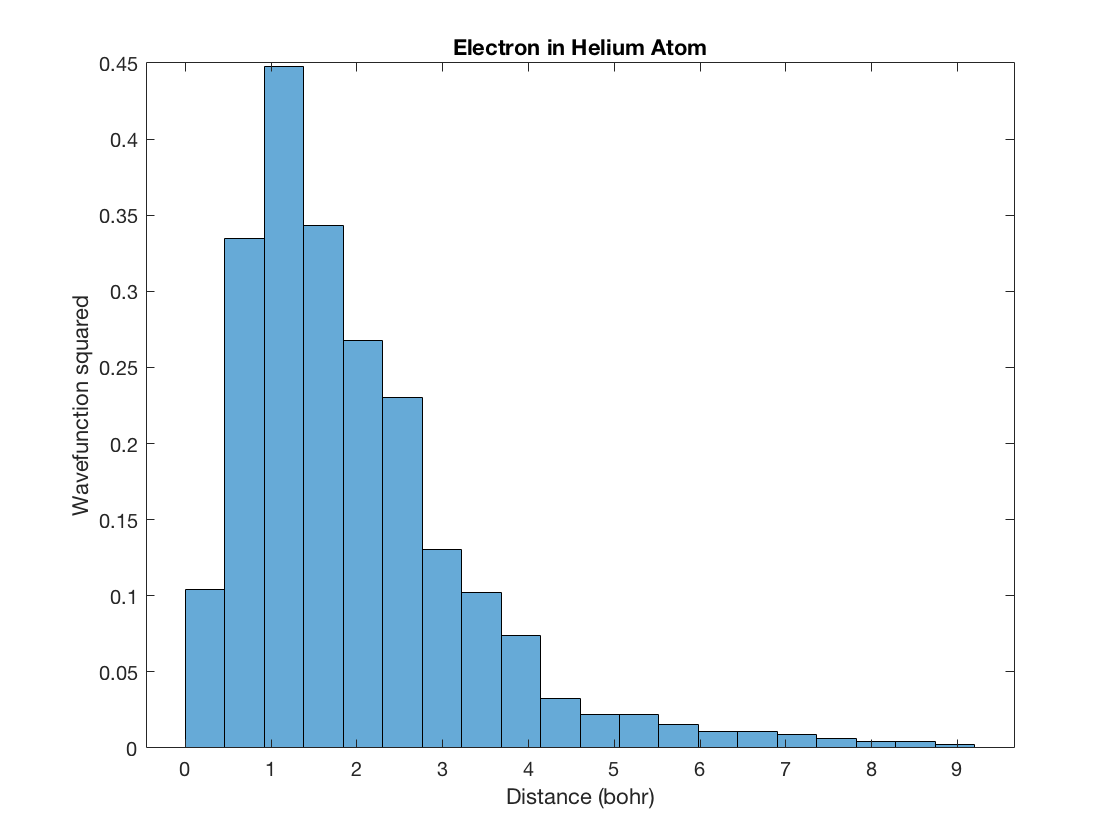

bins = 20;
normRs = [];
for i = 1:M0
    normRs(i) = norm(R(i,4:6));
end
rmax = 10;
rvals = (0:0.001:1).*rmax;
histogram(normRs,bins,'Normalization','pdf');
title('Electron in Helium Atom')
xlabel('Distance (bohr)')
ylabel('Wavefunction squared')

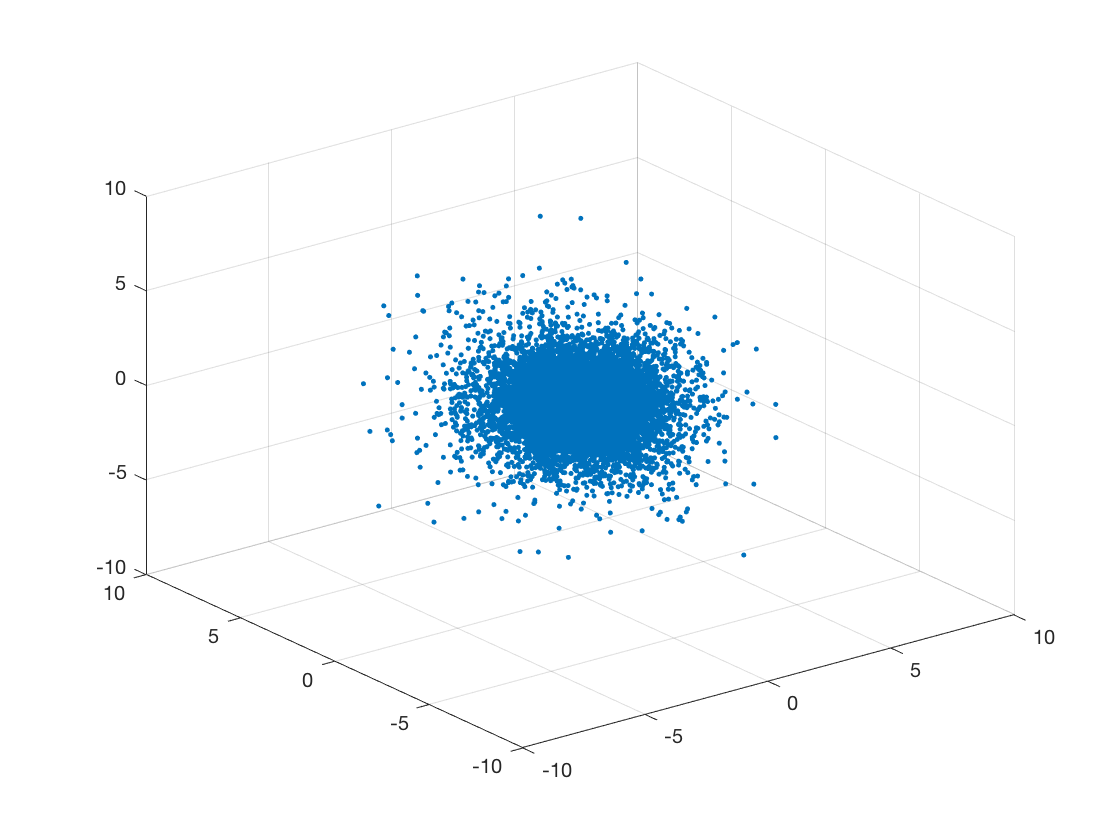

bins = 20;
normRs = [];
for i = 1:M0
    normRs(i) = norm(R(i,4:6));
end
rmax = 10;
rvals = (0:0.001:1).*rmax;
histogram(normRs,bins,'Normalization','pdf');scatter3(R(:,1),R(:,2),R(:,3),'.')

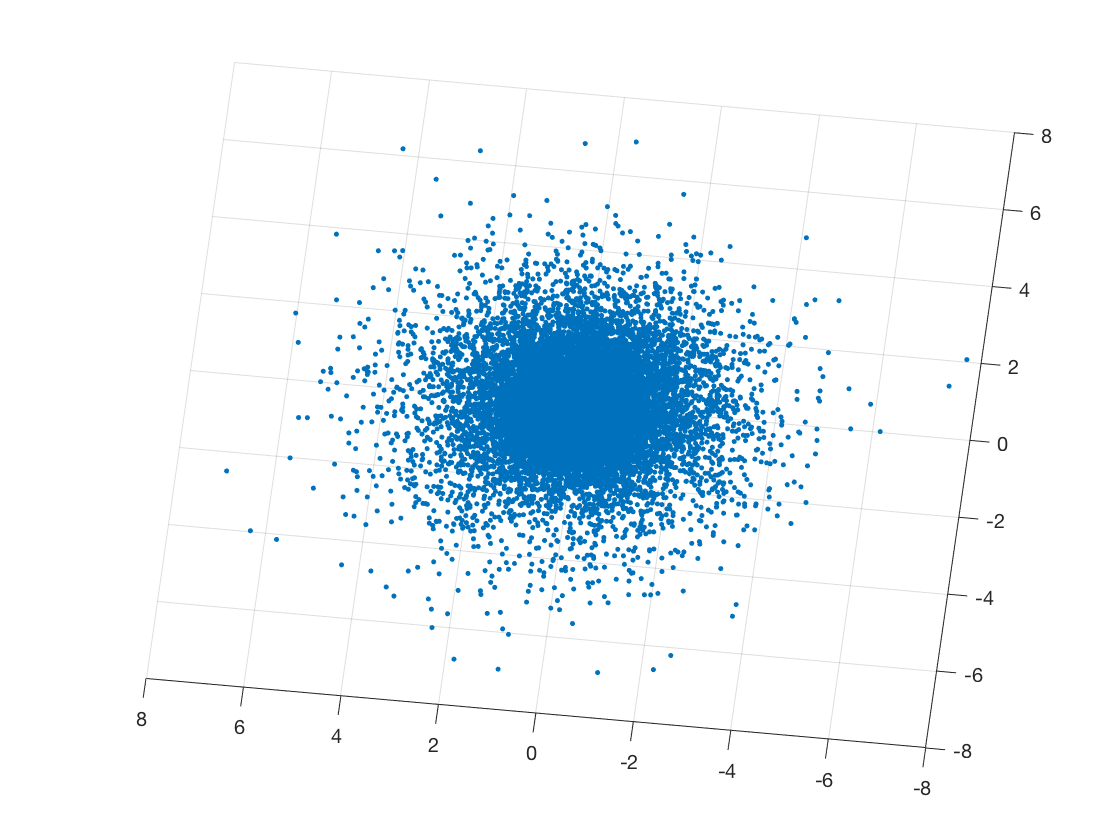

scatter3(R(:,1),R(:,2),R(:,3),'.')


% image(hist3(R(:,1:2),[50 50]).*10)
% contourf(hist3(R(:,1:2),[20 20]))

## Guided Helium

% System parameters
dims = 6;                                                       % 6 dimensions (3 dims * 2 electrons)
V = @(r) -2/norm(r(1:3))-2/norm(r(4:6))+1/norm(r(1:3)-r(4:6));  % Helium potential
b = 1.6875;                                                     % Constant for trial wave function
pT = @(r) exp(-b*(norm(r(1:3))+norm(r(4:6))));                  % Trial wave function
norm2 = @(r) [ones(3,1)*norm(r(1:3));ones(3,1)*norm(r(4:6))];   % Used below
EL = @(r) -D*sum(r.^2*b./norm2(r).^3-b./norm2(r)+(r*b./norm2(r)).^2)+V(r);  % Local energy
F = @(r) -2*b*r./norm2(r);                                                  % Quantum force

% DMC simulation parameters
M0 = 100;                               % Initial number of walkers
R0 = (rand(M0,dims)-0.5).*2;            % Starting positions for walkers
E0 = -3;                                % Initial energy estimate
dt = 0.01;                              % Time step
steps = 1000;                           % Number of Monte Carlo steps
bSteps = 20;                            % Number of steps to adjust energy E after
a = 0.01;                               % Proportionality factor

tic; [E, R] = DMC(D,dims,pT,EL,F,E0,dt,M0,steps,bSteps,a); toc;

Elapsed time is 4.100657 seconds.


E

E =   -2.906813606670448


length(R)

ans =     89
